syms M(t) k t0 M0
ode = diff(M,t) == k

$$ode(t) = \frac{\partial }{\partial t}M\left(t\right)=k$$

cond = M(t0) == M0;
MSol(t) = dsolve(ode,cond)

$$MSol(t) = M_{0}+k\,t-k\,t_{0}$$

%MSol(t) = collect(MSol(t))


Modelo 2

clc, clear
syms M(t) k t0 M0 S
ode = diff(M,t) == k - S;
cond = M(t0) == M0;
MSol(t) = dsolve(ode,cond)

$$MSol(t) = M_{0}-t\,\left(S-k\right)+t_{0}\,\left(S-k\right)$$

MSol(t) = collect(MSol(t), [k S])

$$MSol(t) = \left(t-t_{0}\right)\,k+\left(t_{0}-t\right)\,S+M_{0}$$

If cond t0 = 0

cond = M(0) == M0;
MSol(t) = dsolve(ode,cond)

$$MSol(t) = M_{0}-t\,\left(S-k\right)$$

MSol(t) = collect(MSol(t), [k S])

$$MSol(t) = t\,k+\left(-t\right)\,S+M_{0}$$

Modelo 3

%clc, clear
syms M(t) k t0 M0 S r
ode = diff(M,t) == k - r*M;
cond = M(t0) == M0;
MSol(t) = dsolve(ode,cond)

$$MSol(t) = \frac{k-{\mathrm{e}}^{-r\,t}\,\left(k\,{\mathrm{e}}^{r\,t_{0}}-M_{0}\,r\,{\mathrm{e}}^{r\,t_{0}}\right)}{r}$$


MSol(t) = collect(MSol(t), exp(r))

$$MSol(t) = \frac{k-{\mathrm{e}}^{-r\,t}\,\left(k\,{\mathrm{e}}^{r\,t_{0}}-M_{0}\,r\,{\mathrm{e}}^{r\,t_{0}}\right)}{r}$$

simplify(MSol)

$$ans(t) = \frac{k-{\mathrm{e}}^{-r\,t}\,\left(k\,{\mathrm{e}}^{r\,t_{0}}-M_{0}\,r\,{\mathrm{e}}^{r\,t_{0}}\right)}{r}$$

Ej 2

syms y(x)
Dy = diff(y);

ode = diff(y,x,2) == -y;
cond1 = y(0) == 2;
cond2 = Dy(0) == 0;
conds = [cond1 cond2];
ySol(x) = dsolve(ode,conds);
ySol = simplify(ySol)

$$ySol(x) = 2\,\cos\left(x\right)$$

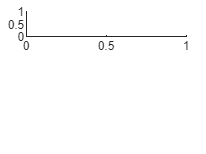


grid on
subplot(3, 1, 1)

plot(out.x(:,2 ), out.dx(:,2 ))

Unable to resolve the name 'out.x'.

subplot(3, 1, 2)
plot(out.x(:,1 ), out.dx(:,1 ))
subplot(3, 1, 3)
plot(out.x(:,3 ), out.dx(:,3 ))


Modelo 4

syms y(x) r x0 y0
Dy = diff(y);

ode = Dy == -r*y;
cond1 = y(x0) == y0;


ySol(x) = dsolve(ode,cond1);
%solve(ySol(x) == y0/2, y)
ySol = simplify(ySol)

Modelo 5

syms y(x) r x0 y0
Dy = diff(y);

ode = Dy == -r*y;
cond1 = y(x0) == y0;


ySol(x) = dsolve(ode,cond1);
%solve(ySol(x) == y0/2, y)
ySol = simplify(ySol)



Ej 3

 clf
syms x

y = x^2 - 3*sin(x)+0.1;
fplot(y, [-10 10])
ylim([-10 50])
xline(0)
yline(0)
round(vpasolve(y == 0, x), 4)



Modelo de crecimiento logístico


$$p^{\prime } =k\cdot p\left(1-\frac{p}{p_{\max } }\right)$$


syms k pmax p(t) t0 p0

Dp = diff(p);

ode = Dp == k*p*(1-(p/pmax));
cond1 = p(t0) == p0;


pSol(t) = dsolve(ode,cond1);
%solve(ySol(x) == y0/2, y)
pSol = simplify(pSol)





Pendulum problem


syms x(t)  t
m = 5;
k = 0.5;
dx = diff(x)
ode = diff(dx) == -k*x/m;
cond1 = x(0) == 1.5;
cond2 = dx(0) == 0;




pSol(t) = dsolve(ode,[cond1, cond2]);
pSol = simplify(pSol)

dx = diff(pSol, t)
vpasolve(dx, t, 20)



Ej 10

clear
syms x(t) u t 
dx(t) = diff(x);
ddx = diff(dx);

ode = diff(x)== -1*(0.5*dx + 2*x + x^2 + 1);
cond1 = x(0) == 1;
cond2 = dx(0) == 1;
dsolve(ode, [cond1, cond2]);






plot(out.x(:,1 ), out.dx(:,1))
    


Importing simulink model to Live script

clc, clear
nombre_modelo = 'ej10';
open(nombre_modelo);% abre una pestaña con el modelo 
                    % (no hace falta abrirlo para simular y hacer cosas con los resultados)
sim(nombre_modelo); %simula el modelo







































Unsupported use of the '=' operator. To compare values for equality, use '=='. To specify name-value arguments, check that name is a valid identifier with no surrounding quotes.

block_diagram does not have a parameter named 'x_min'